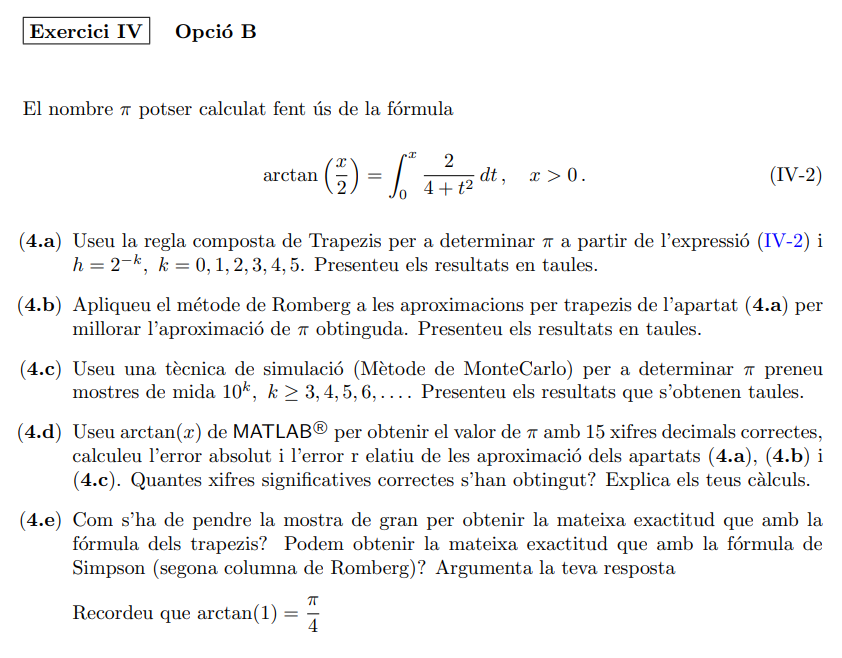

clear all
format longG

f = @(x) 2./(4 + x.^2);
a = 0;
b = 2;

Para facilitar el trabajo, he realizado todos los calculos en base a pi/4, de forma que para obtener el resultado pi, solo habria que multiplicar los resultados de todas las integrales por 4.

### Trapezis

h = 1./2.^(0:5)';
for k = 0:5
    trapezis(k+1).h = h(k+1);
    trapezis(k+1).value = trapz(f,a,b,h(k+1));
    [ea, er, ~] = funerror(trapezis(k+1).value, atan(1));
    trapezis(k+1).ea = ea;
    trapezis(k+1).er = er;
    trapezis(k+1).correctDec = correctDec(trapezis(k+1).value, atan(1));
    
end
trapezis

trapezis = 1×6 struct array with fields:
    h
    value
    ea
    er
    correctDec


### Romberg

romberg_value = romberg(f,a,b);
RombergDisp(f,a,b,6); % Habria que multiplicar por 4 todos los valores para ser pi

0.750000000000000
0.775000000000000	0.783333333333333	
0.782794117647059	0.785392156862745	0.785529411764706	
0.784747123622772	0.785398125614677	0.785398523531472	0.785396445940468	
0.785235403010347	0.785398162806206	0.785398165285641	0.785398159599199	0.785398166319429	
0.785357473293744	0.785398163388209	0.785398163427009	0.785398163397507	0.785398163412403	0.785398163409561	
0.785387990871414	0.785398163397304	0.785398163397910	0.785398163397449	0.785398163397448	0.785398163397434	0.785398163397431	


romberg = [...
[0.750000000000000      0                       0                       0                       0                       0                       0];...
[0.775000000000000	0.783333333333333	0                       0                       0                       0                       0];...
[0.782794117647059	0.785392156862745	0.785529411764706	0                       0                       0                       0];...
[0.784747123622772	0.785398125614677	0.785398523531472	0.785396445940468	0                       0                       0];...
[0.785235403010347	0.785398162806206	0.785398165285641	0.785398159599199	0.785398166319429	0                       0];...
[0.785357473293744	0.785398163388209	0.785398163427009	0.785398163397507	0.785398163412403	0.785398163409561	0];...
[0.785387990871414	0.785398163397304	0.785398163397910	0.785398163397449	0.785398163397448	0.785398163397434	0.785398163397431]];

array2table([(0:6)' romberg], "VariableNames",{'k','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6','ER_7'})

ans = 7×8 table
    k     ER_1       ER_2       ER_3       ER_4      ER_5      ER_6      ER_7 
    _    _______    _______    _______    ______    ______    ______    ______

    0       0.75          0          0         0         0         0         0
    1      0.775    0.78333          0         0         0         0         0
    2    0.78279    0.78539    0.78553         0         0         0         0
    3    0.78475     0.7854     0.7854    0.7854         0         0         0
    4    0.78524     0.7854     0.7854    0.7854    0.7854         0         0
    5    0.78536     0.7854     0.7854    0.7854    0.7854    0.7854         0
    6    0.78539     0.7854     0.7854    0.7854    0.7854    0.7854    0.7854


romberg;
reales = romberg;
reales(reales>0) = atan(1);
[ea_romberg,er_romberg,~] = funerror(romberg,reales);

for j = 1:size(romberg,2)
    for i = 1:size(romberg,1)
        dec_romberg(i,j) = correctDec(romberg(i,j),atan(1));
    end
end
dec_romberg(dec_romberg < 0) = 0;


ROMBERG = array2table([(0:6)' romberg], "VariableNames",{'k','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6','ER_7'})

ROMBERG = 7×8 table
    k     ER_1       ER_2       ER_3       ER_4      ER_5      ER_6      ER_7 
    _    _______    _______    _______    ______    ______    ______    ______

    0       0.75          0          0         0         0         0         0
    1      0.775    0.78333          0         0         0         0         0
    2    0.78279    0.78539    0.78553         0         0         0         0
    3    0.78475     0.7854     0.7854    0.7854         0         0         0
    4    0.78524     0.7854     0.7854    0.7854    0.7854         0         0
    5    0.78536     0.7854     0.7854    0.7854    0.7854    0.7854         0
    6    0.78539     0.7854     0.7854    0.7854    0.7854    0.7854    0.7

ERROR_ABSOLUTO = array2table([(0:6)' ea_romberg], "VariableNames",{'k','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6','ER_7'})

ERROR_ABSOLUTO = 7×8 table
    k       ER_1          ER_2          ER_3          ER_4          ER_5          ER_6          ER_7   
    _    __________    __________    __________    __________    __________    __________    __________

    0      0.035398             0             0             0             0             0             0
    1      0.010398     0.0020648             0             0             0             0             0
    2      0.002604    6.0065e-06    0.00013125             0             0             0             0
    3    0.00065104    3.7783e-08    3.6013e-07    1.7175e-06             0             0             0
    4    0.00016276    5.9124e-10    1.8882e-09    3.7982e-09     2.922e-09 

ERROR_RELATIVO = array2table([(0:6)' er_romberg], "VariableNames",{'k','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6','ER_7'})

ERROR_RELATIVO = 7×8 table
    k       ER_1          ER_2          ER_3          ER_4          ER_5          ER_6          ER_7   
    _    __________    __________    __________    __________    __________    __________    __________

    0       0.04507           NaN           NaN           NaN           NaN           NaN           NaN
    1      0.013239      0.002629           NaN           NaN           NaN           NaN           NaN
    2     0.0033156    7.6478e-06    0.00016711           NaN           NaN           NaN           NaN
    3    0.00082893    4.8107e-08    4.5854e-07    2.1867e-06           NaN           NaN           NaN
    4    0.00020723    7.5279e-10    2.4041e-09    4.8361e-09    3.7204e-09 

DECIMALES_CORRECTOS = array2table([(0:6)' dec_romberg], "VariableNames",{'k','ER_1','ER_2','ER_3','ER_4','ER_5','ER_6','ER_7'})

DECIMALES_CORRECTOS = 7×8 table
    k    ER_1    ER_2    ER_3    ER_4    ER_5    ER_6    ER_7
    _    ____    ____    ____    ____    ____    ____    ____

    0     1        0       0       0       0       0       0 
    1     1        2       0       0       0       0       0 
    2     2        4       3       0       0       0       0 
    3     2        7       6       5       0       0       0 
    4     3        8       8       8       8       0       0 
    5     4       10      10      12      10      10       0 
    6     4       12      12      14      15      13      13 


### MonteCarlo

for k = 3:8
    monteCarlo(k-2).k = k;
    monteCarlo(k-2).value = MonteCarlo(f,a,b,0,0.5,10^k,false);
    [ea, er, ~] = funerror(monteCarlo(k-2).value, atan(1));
    monteCarlo(k-2).ea = ea;
    monteCarlo(k-2).er = er;
    monteCarlo(k-2).correctDec = correctDec(monteCarlo(k-2).value, atan(1));
end

monteCarlo

monteCarlo = 1×6 struct array with fields:
    k
    value
    ea
    er
    correctDec
